gpuDevice(1);
imds1 = imageDatastore("C:\Users\91839\Documents\MATLAB\Project 1\ScreenShot Rebroadcast\","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain1, imdsValidation1] = splitEachLabel(imds1,0.6,"randomized");

% Resize the images to match the network input layer.

net = mobilenetv2;
inputSize= net.Layers(1).InputSize;

augimdsTrain1 = augmentedImageDatastore(inputSize,imdsTrain1,"ColorPreprocessing","gray2rgb");
augimdsValidation1 = augmentedImageDatastore(inputSize,imdsValidation1,"ColorPreprocessing","gray2rgb");

% Modify the last few layers to match the number of classes
numClasses = 2;
layers = [
    globalAveragePooling2dLayer('Name','pool')
    fullyConnectedLayer(64,'Name','fc','BiasLearnRateFactor',10,'WeightLearnRateFactor',10)
    dropoutLayer('Name','dropout')
    fullyConnectedLayer(numClasses,'Name','fc_final','BiasLearnRateFactor',10,'WeightLearnRateFactor',10)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classoutput')];

lgraph = layerGraph(net)

lgraph =   LayerGraph with properties:

         Layers: [154×1 nnet.cnn.layer.Layer]
    Connections: [163×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_Logits'}


Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:46 |       56.25% |       50.91% |       0.6880 |       0.6933 |      1.0000e-04 |
|       1 |          10 |       00:01:57 |       40.62% |       49.16% |       0.6995 |       0.6944 |      1.0000e-04 |
|       1 |          20 |       00:03:11 |       53.12% |       45.50% |       0.6943 |       0.6958 |      1.0000e-04 |
|       1 |          30 |       00:04:25 |       42.19% |       43.60% |       0.6995 |   

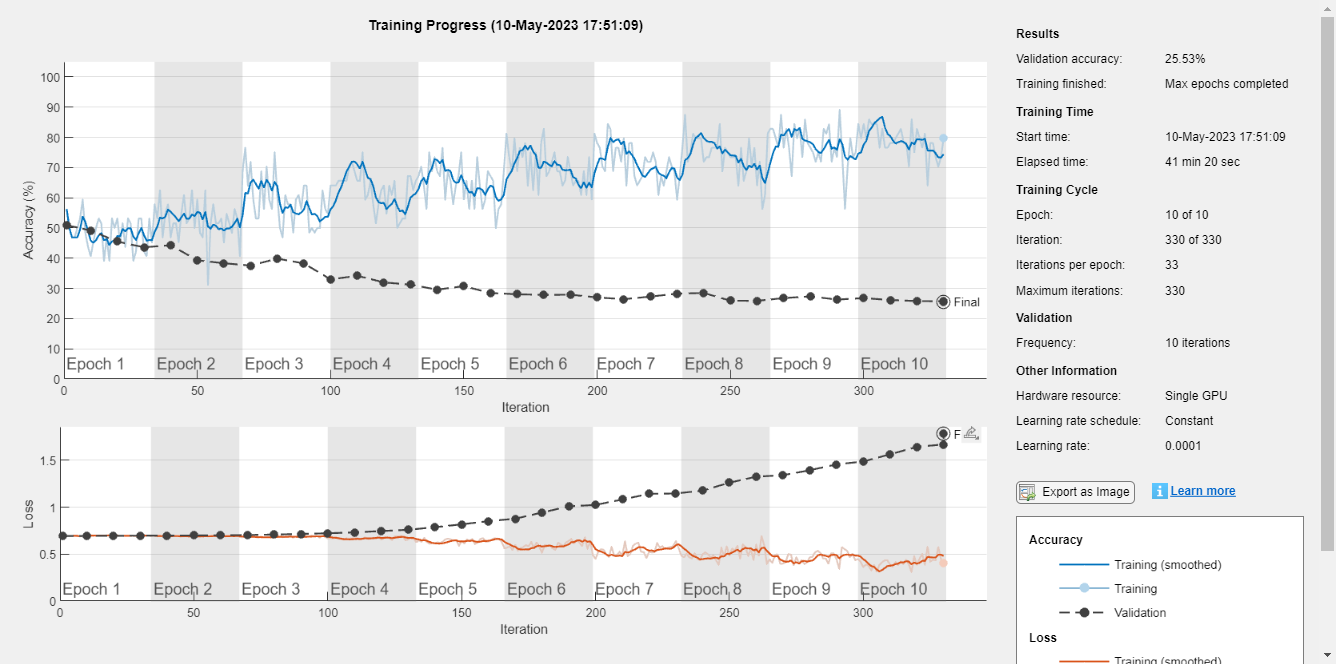

lgraph = replaceLayer(lgraph, 'ClassificationLayer_Logits', layers,'ReconnectBy','name');

options = trainingOptions('adam', ...
    'MiniBatchSize', 64, ...
    'MaxEpochs', 10, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsValidation1, ...
    'ValidationFrequency', 10, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

% Train the model on the training set
net = trainNetwork(augimdsTrain1,lgraph,options);


% Evaluate the model on the test set
YTest = classify(net, test_set);

Unrecognized function or variable 'test_set'.

accuracy = mean(YTest == test_set.Labels);
fprintf('Test accuracy: %0.2f%%\n', accuracy*100);